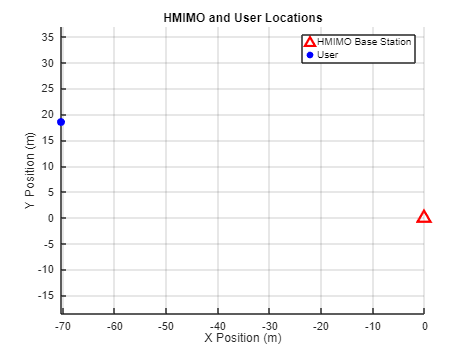

% Simulation Parameters
M = 16;
N = 16;
total_antennas = M * N;
nSamples = 1000;  % Number of time samples to simulate time-varying channels
SNR_dB = 10;
SNR = 10^(SNR_dB/10);
lambda = 3e8 / 28e9;

% Generate Planar Array Positions
dx = lambda / 2;
dy = lambda / 2;
[x_grid, y_grid] = meshgrid(0:dx:(M-1)*dx, 0:dy:(N-1)*dy);
antenna_positions = [x_grid(:), y_grid(:)];

% HMIMO Base Station Position (fixed at the origin)
hmimo_x = 0;
hmimo_y = 0;

% Generate a Random User Position
user_distance = 20 + (80 - 20) * rand;
user_angle = 2 * pi * rand;
user_x = user_distance * cos(user_angle);
user_y = user_distance * sin(user_angle);

figure;
hold on;
plot(hmimo_x, hmimo_y, 'r^', 'MarkerSize', 10, 'LineWidth', 2); % HMIMO base station
scatter(user_x, user_y, 50, 'b', 'filled'); % User position
title('HMIMO and User Locations');
xlabel('X Position (m)');
ylabel('Y Position (m)');
legend('HMIMO Base Station', 'User');
axis equal;
grid on;
hold off;

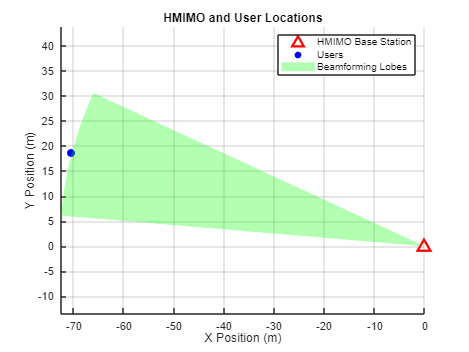


beamwidth_deg = 20;
beamwidth_rad = deg2rad(beamwidth_deg);

figure;
hold on;
plot(hmimo_x, hmimo_y, 'r^', 'MarkerSize', 10, 'LineWidth', 2); % HMIMO base station
scatter(user_x, user_y, 50, 'b', 'filled'); % User position
title('HMIMO and User Locations');
xlabel('X Position (m)');
ylabel('Y Position (m)');
legend('HMIMO Base Station', 'User');
axis equal;
grid on;

% Calculate the angle between HMIMO and user
dx = user_x - hmimo_x;
dy = user_y - hmimo_y;
angle_to_user = atan2(dy, dx); 

% Define the sector (beam lobe) parameters
theta_start = angle_to_user - beamwidth_rad/2;
theta_end = angle_to_user + beamwidth_rad/2;
r_max = sqrt(dx^2 + dy^2); 

% Create the beam lobe as a sector
theta = linspace(theta_start, theta_end, 100);
r = linspace(0, r_max, 50); 
[Theta, R] = meshgrid(theta, r);
[X, Y] = pol2cart(Theta, R);

% Shift the beam lobe to HMIMO position
X = X + hmimo_x;
Y = Y + hmimo_y;

% Beam lobe color intensity proportional to beamforming gain
beam_intensity = 1;
beam_color = [0, 1, 0];

% Plot the beam lobe
surf(X, Y, zeros(size(X)), 'FaceColor', beam_color, 'EdgeColor', 'none', 'FaceAlpha', 0.3);

% Update plot with legend
legend('HMIMO Base Station', 'Users', 'Beamforming Lobes');
hold off;
view(2);

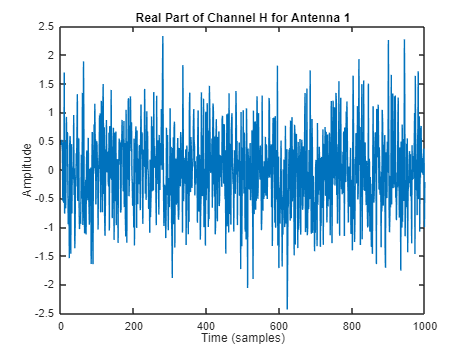



% Initialize variables for storing and plotting
H = zeros(total_antennas, nSamples);
beamforming_gain = zeros(1, nSamples);

% Generate Rayleigh fading channel matrix (H)
for timeIdx = 1:nSamples
    h_real = sqrt(0.5) * randn(total_antennas, 1);
    h_imag = sqrt(0.5) * randn(total_antennas, 1);
    H(:, timeIdx) = h_real + 1i * h_imag;
end

figure;
plot(squeeze(real(H(1, :))));
title('Real Part of Channel H for Antenna 1');
xlabel('Time (samples)');
ylabel('Amplitude');

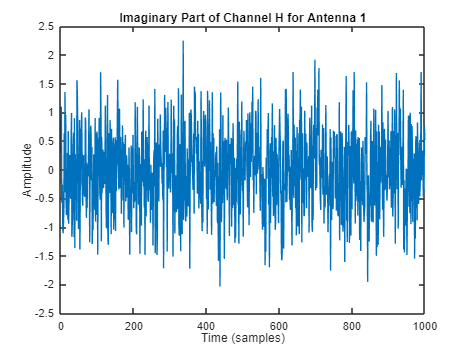


figure;
plot(squeeze(imag(H(1, :))));
title('Imaginary Part of Channel H for Antenna 1');
xlabel('Time (samples)');
ylabel('Amplitude');


% Digital Beamforming Vector (V)
V = sqrt(SNR) / norm(H(:, 1)); % Normalized for the first time sample

fprintf('Digital Beamforming Vector (V):\n');

Digital Beamforming Vector (V):


disp(V);

    0.1986



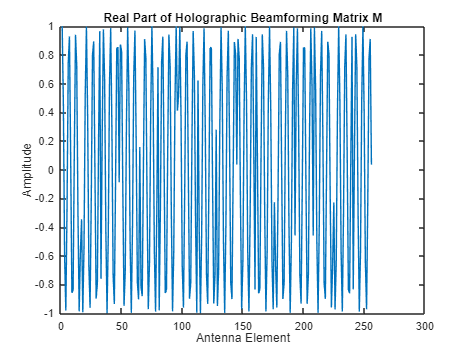


% Holographic Beamforming Matrix (M)
M_matrix = exp(-1j * 2 * pi / lambda * (antenna_positions(:, 1) * sin(theta_user) * cos(phi_user) ...
             + antenna_positions(:, 2) * sin(theta_user) * sin(phi_user))); % Reference wave phase

figure;
plot(real(M_matrix));
title('Real Part of Holographic Beamforming Matrix M');
xlabel('Antenna Element');
ylabel('Amplitude');

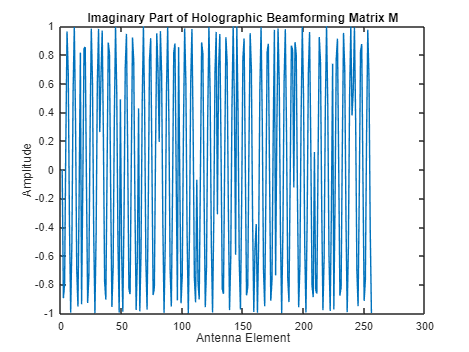


figure;
plot(imag(M_matrix));
title('Imaginary Part of Holographic Beamforming Matrix M');
xlabel('Antenna Element');
ylabel('Amplitude');

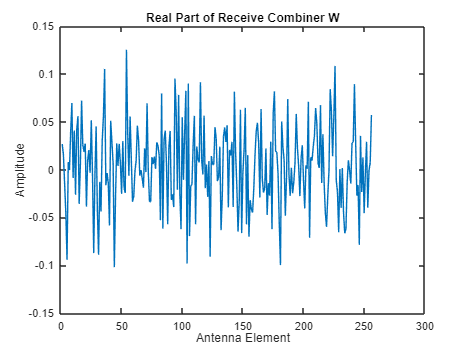


% Receive Combiner Vector (W) for the initial time sample
W = H(:, 1) / norm(H(:, 1));

figure;
plot(real(W));
title('Real Part of Receive Combiner W');
xlabel('Antenna Element');
ylabel('Amplitude');

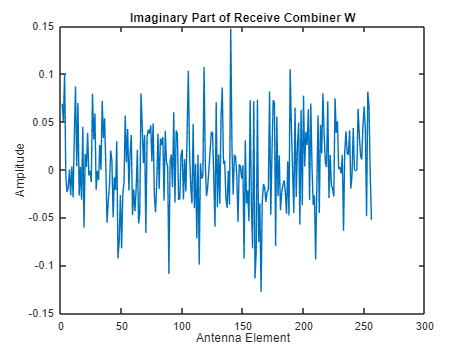


figure;
plot(imag(W));
title('Imaginary Part of Receive Combiner W');
xlabel('Antenna Element');
ylabel('Amplitude');

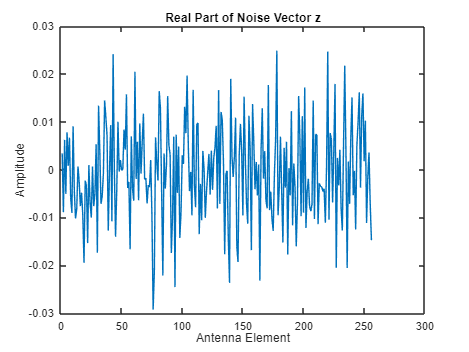


% Transmitted Signal (s)
s = 1 + 1j;

% Additive White Gaussian Noise (z)
z = 0.01 * (randn(total_antennas, 1) + 1j * randn(total_antennas, 1)); % Noise vector

figure;
plot(real(z));
title('Real Part of Noise Vector z');
xlabel('Antenna Element');
ylabel('Amplitude');

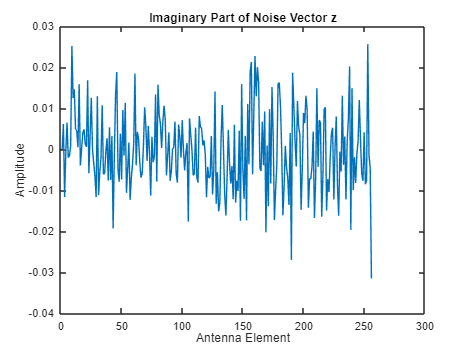


figure;
plot(imag(z));
title('Imaginary Part of Noise Vector z');
xlabel('Antenna Element');
ylabel('Amplitude');

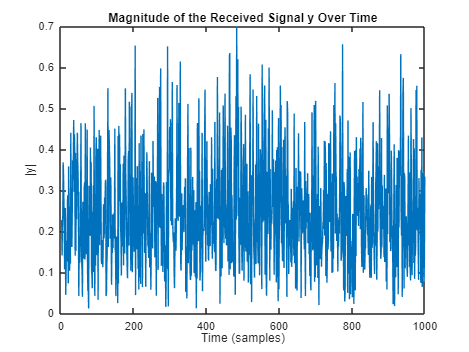


% Calculate the Final Received Signal y for Each Time Index
y = zeros(1, nSamples);
for timeIdx = 1:nSamples
    h_t = H(:, timeIdx);
    W = h_t / norm(h_t);
    y(timeIdx) = W' * (h_t .* M_matrix) * V * s + W' * z;
end

figure;
plot(1:nSamples, abs(y));
title('Magnitude of the Received Signal y Over Time');
xlabel('Time (samples)');
ylabel('|y|');